Solving the reaction-diffusion systems in the paper directly instead of decoupling the two eqns

Bcs: Neumann + Neumann

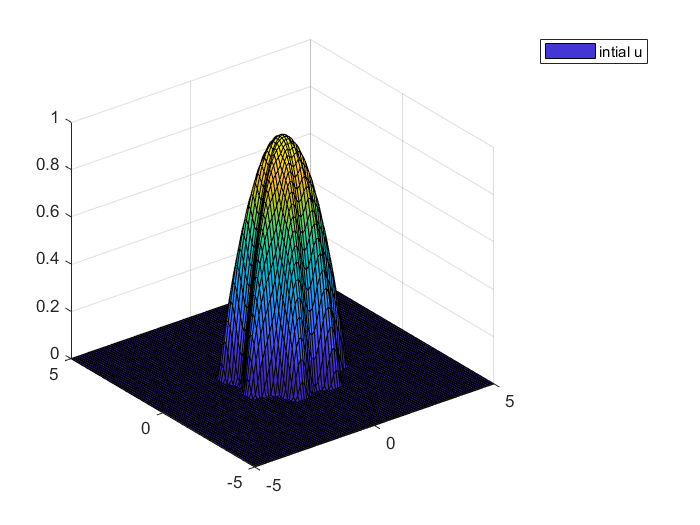

clc;clear;
close;
filename='final_lambda40_l8.gif'; %record evolution


% Parameters
lm = -5; lp = 5;   % Length of the domain 
t0 = 0;      % Initial time
T = 2000;                % Final time      
Mx = 51;       My = 51;      
%N = 101;     % Number of grid points
dx = (lp-lm)/(Mx-1);  % Spatial step size dx 
dy = (lp-lm)/(My-1);  % Spatial step size dy 
dt = 0.001;    % Time step size  dt
m = 40;        % power
tol = 1e-2;

% Initialize grid
x = [lm :dx :lp];    % x row
y = [lm :dy :lp]' ;  % y column
%t = [t0: dt: T];
r = (x.^2 + y.^2).^(1/2);

G0 = 1;
lambda = 40; % consumption rate %0.8  %2 %100 
tau = 1/10; % characteristic time scale   %adjust as 1/10
c_B = 100; % concentration in the background surrounding liquid

% initial condition
delta = 0.05;
l = 8;
u0 = max(1 -(x.^2+y.^2)./4 .* (1+0.1*cos(l*atan2(y,x))).^2,0 )';
c_simi = @(r,t) max( 1 - m /(4*(m+1)^2) .*(r.*(t+1).^(-1/(2*m+2))).^2  , 0 ).^(1/m).*(t+1).^(-1/(m+1));
c0 = c_simi(r,0)';
%c0 = c_B*ones(Mx,My)';
c = zeros(Mx,My);

% initial surface
surf(x,y,u0')
legend ('intial u')

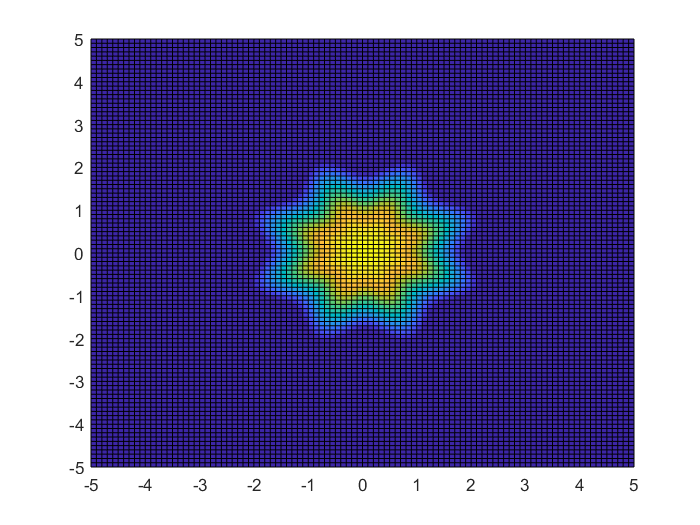

surf(x,y,u0')
view(2)

%hold 

t = [];
t1 = t0;
n = 0;           % record number of evolution
T_track = [ ];   % keep track of T
dt_track = [ ];  % keep track of dt
dt0 = dt;

tic
% Loop over time steps
while t1 < T   
    %if the last 5 point of u is not zero, stop evolution
    if ( u0(Mx-10,My-10) ~= 0 )
        break
    else
        
        % Compute the next time step
        u = u0;
        c = c0;
        % Perform a full step 
        [uA,cA,Psi] = timestep(G0,lambda,tau,c_B,dx,dy,dt,u0,c0,Mx,My,m);
        
        % Perform two half steps 
        [u1,c1,Psi_1] = timestep(G0,lambda,tau,c_B,dx,dy,dt/2,u0,c0,Mx,My,m);
        [u2,c2,Psi_2] = timestep(G0,lambda,tau,c_B,dx,dy,dt/2,u0,c0,Mx,My,m);
        
        % Calculate the error estimate
        err = max(max(abs(uA - u2)));
        
        % Check if the error is within a desired tolerance
        if (err < tol )
            % Accept the step
            n = n+1;
            u0 = uA;
            c0 = cA;
            
            t = [t t1+dt];
            T_track = [T_track t1]; % keep total time of T
            
            surf(x,y,u')
            view(2)
            %immediately refresh the current drawing window
            drawnow;
            %get the current drawing window's image and return image data related to movie frames
            im=frame2im(getframe(gcf)); 
            %Convert RGB images to index images
            [A,map]=rgb2ind(im,256);     
            if n==1
                % write the specified gif file in overwrite mode first
                imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0.05);
            else
                %write each frame into a gif file in append mode again
                imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);
            end
                        
            dt0 = dt;
            dt_track = [dt_track dt0];  % keep track of dt
            dt = 0.98*dt *abs(tol/err).^(0.2);
        else
            % Reject the step and decrease the time step size
            dt = dt/2;
        end    
        t1 = t1+dt0;    
    end
end

toc

历时 698.610141 秒。


function [u,c,Psi] = timestep(G0,lambda,tau,c_B,dx,dy,dt,u0,c0,Mx,My,m)
    u = u0;
    c = c0;
    %jj = jj+1 ;
    for k=1:10  %(newton iterations at each time)        

       % define Psi 
       for j = 1:My
           for i = 1:Mx
               % define a function H(u) (depends on density u) to turn off terms (inside and outside tumor)
               k1 = 10;
               if u(i,j) <= 0, H(i,j) = 0; else, H(i,j) = tanh(k1*u(i,j)); end       
               % derivative of H (dH)
               if u(i,j) <= 0, dH(i,j) = 0; else, dH(i,j) = k1*(sech(k1*u(i,j)))^2; end       
               % define \Psi(u,c) from H(u), where \Psi depends both on density (u) and concentration (c) 
               Psi(i,j) = -(c_B - c(i,j)) + ( lambda*u(i,j) *c(i,j) + (c_B - c(i,j)) ) * H(i,j) ;
               % derivatives of Psi w.r.t u (Psi_u(i)) and w.r.t c (Psi_c(i))
               Psi_u(i,j) = lambda*c(i,j)*H(i,j) + lambda*u(i,j)*c(i,j)*dH(i,j) + (c_B-c(i,j))*dH(i,j); %product rule
               Psi_c(i,j) = 1 + H(i,j)*lambda*u(i,j) - H(i,j);
            end  %end i = 1:Mx
        end  % end j = 1:My
       
        % calculate F
        for j = 1:My
           for i = 1:Mx
               uc = u(i,j); % center pt
               cc = c(i,j);
               if (i==1),  um = u(i+1,j); else, um = u(i-1,j); end 
               if (i==Mx), up = u(i-1,j); else, up = u(i+1,j); end
               if (j==1),  ud = u(i,j+1); else, ud = u(i,j-1); end   
               if (j==My), uu = u(i,j-1); else, uu = u(i,j+1); end     
               Fu(i,j) = uc - u0(i,j) - (m/(m+1))*(dt/dx^2)*(up^(m+1)-2*uc^(m+1) ...
                         +um^(m+1))-(m/(m+1))*(dt/dy^2)*(uu^(m+1)-2*uc^(m+1)+ud^(m+1)) - dt*uc*G0*cc;    
              
               if (i==1),  cm = c(i+1,j); else, cm = c(i-1,j); end 
               if (i==Mx), cp = c(i-1,j); else, cp = c(i+1,j); end
               if (j==1),  cd = c(i,j+1); else, cd = c(i,j-1); end   
               if (j==My), cu = c(i,j-1); else, cu = c(i,j+1); end 
               Fc(i,j) = ( c(i,j) - c0(i,j) ) - (dt/dx^2)*(cp-2*c(i,j) ...
                         +cm)/tau - (dt/dy^2)*(cu-2*c(i,j)+cd)/tau + dt*Psi(i,j)/tau ;
           end % end i
        end   %F

        F = [Fu; Fc];

         % Jacobian matrix is composed by block matrix A, B, C, D (see notes)
         % x direction
         % A: Fu w.r.t. u w.r.t x: JxA  
        for j = 1: My
            JxA=zeros(Mx,Mx); 
            JxB=zeros(Mx,Mx); 
            JxC1=zeros(Mx,Mx); 
            JxD1=zeros(Mx,Mx); 
            for  i = 2:Mx-1    
                JxA(i,i-1) = - (m/(m+1)) * (dt/dx^2) * 1*(m+1)*u(i-1,j)^m ;
                JxA(i,i) = 1 - (m/(m+1)) * (dt/dx^2) * ( (-2)*(m+1)*u(i,j)^m ) - dt*G0*c(i,j) ;
                JxA(i,i+1) = -  (m/(m+1)) * (dt/dx^2) * 1*(m+1)*u(i+1,j)^m ;

                JxD1(i, i-1) = -(dt/dx^2)/tau;
                JxD1(i, i) = 1.0 + 2*(dt/dx^2)/tau + (7/8)*dt*Psi_c(i,j)/tau ;
                JxD1(i, i+1) = -(dt/dx^2)/tau;

                JxB(i,i) = -dt*u(i,j)*G0;

                JxC1(i,i) =  (7/8)*dt*Psi_u(i,j)/tau;
                
            end 
            
            % boundary
            JxA(1, 1) = 1 +2*(m/(m+1)) * (dt/dx^2)*(m+1)*u(1,j)^m - dt*G0*c(1,j);  
            JxA(1, 2) = -2*(m/(m+1)) * (dt/dx^2)*(m+1)*u(2,j)^m;  
            JxA(Mx, Mx-1) = -2*(m/(m+1)) *(dt/dx^2)*(m+1)*u(Mx-1,j)^m;  
            JxA(Mx, Mx) = 1 +2*(m/(m+1)) *(dt/dx^2)*(m+1)*u(Mx,j)^m - dt*G0*c(Mx,j);

            JxD1(1, 1) = 1.0 +2*(dt/dx^2)/tau+(7/8)*dt*Psi_c(1,j)/tau;
            JxD1(1, 2) = -2*(dt/dx^2)/tau;
            JxD1(Mx, Mx-1) = -2*(dt/dx^2)/tau;
            JxD1(Mx, Mx) = 1.0 + 2*(dt/dx^2)/tau+(7/8)*dt*Psi_c(Mx,j)/tau ;
            
            JxB(1,1) = -dt*u(1,j)*G0;
            JxB(Mx,Mx) = -dt*u(Mx,j)*G0;
            
            JxC1(1,1) =  (7/8)*dt*Psi_u(1,j)/tau;
            JxC1(Mx,Mx) =  (7/8)*dt*Psi_u(Mx,j)/tau;

            % form Jx
            Jx = [JxA JxB ; JxC1 JxD1];             
            Vx(:,j)= -sparse(Jx) \ F(:,j);            
        end
        
        %VVx = zeros(1*Mx,2*My) ;
        VVx = [Vx(1:Mx,:) Vx(Mx+1:2*Mx,:)];
        %break
        
        % y direction
        % A: Fu w.r.t. u w.r.t y: JyA
        for i = 1: Mx
            JyA=zeros(My,My);
            JyB=zeros(My,My);
            JyC1=zeros(My,My);
            JyD1=zeros(My,My);
            for j = 2:My-1
                 JyA(j, j-1) = -(m/(m+1)) * (m+1)*(dt/dy^2)*u(i,j-1)^m ; 
                 JyA(j, j) = 1+2*(m/(m+1)) * (m+1)*(dt/dy^2)*u(i,j)^m - dt*G0*c(i,j) ; 
                 JyA(j, j+1) = -(m/(m+1)) * (m+1)*(dt/dy^2)*u(i,j+1)^m ; 

                 JyD1(j, j-1) =-(dt/dy^2)/tau;
                 JyD1(j, j) = 1.0 + 2*(dt/dy^2)/tau + (1/8)*dt*Psi_c(i,j)/tau ;
                 JyD1(j, j+1) = -(dt/dy^2)/tau;

                 JyB(j, j) = -dt*u(i,j)*G0;

                 JyC1(j, j) =  (1/8)*dt*Psi_u(i,j)/tau;
            end

            % boundary
            JyA(1, 1) = 1 +2*(m/(m+1)) * (dt/dy^2)*(m+1)*u(i,1)^m - dt*G0*c(i,1) ; 
            JyA(1, 2) = -(m/(m+1)) * (dt/dy^2)*(m+1)*2*u(i,2)^m ;
            JyA(My, My-1) = -2*(m/(m+1)) * (dt/dy^2)*(m+1)*u(i,My-1)^m ;
            JyA(My, My) = 1 +2*(m/(m+1)) * (dt/dy^2)*(m+1)*u(i,My)^m - dt*G0*c(i,My) ;

            JyD1(1, 1) = 1.0 + 2*(dt/dy^2)/tau + (1/8)*dt*Psi_c(i,1)/tau;
            JyD1(1, 2) = -2*(dt/dy^2)/tau;
            JyD1(My, My-1) = -2*(dt/dy^2)/tau  ;
            JyD1(My, My) = 1.0 + 2*(dt/dy^2)/tau +(1/8)*dt*Psi_c(i,My)/tau;

            JyB(1, 1) = -dt*u(i,1)*G0;
            JyB(My, My) = -dt*u(i,My)*G0;

            JyC1(1, 1) =  (1/8)*dt*Psi_u(i,1)/tau;
            JyC1(My, My) =  (1/8)*dt*Psi_u(i,My)/tau;
    
            % form Jy
            Jy = [JyA JyB ; JyC1 JyD1];
            
            Wy(i,:) = sparse(Jy) \ VVx(i,:)';        
        end
        
        delta_u = Wy(:,1:My);
        delta_c = Wy(:,My+1:2*My);
        u = u + delta_u;
        c = c + delta_c;
        
    end % end newton iteration
end

